# EME 165 Project 2

by, Alex Lewis

## Establishing Properties

clear
%Water Properties at Film Temp (40C)
VA_w = .019/60; %m^3/s
mu_w = .000653; %Ns/m^3
rho_w = 1000; %kg/m^3
Mdot_w = VA_w*rho_w; %kg/s
Cp_w = 4204; %J/KgC
k_w = .6298; %W/mK
Tw_i = 50+273; %K
Tw_o = 30+273; %K
Pr_w = 4.5; %Pandtl #
dP_w_max = 10000; %Pa

%Air Properties at 25C
VA_air = 2; %m^3/s
rho_air = 1.18; %kg/m^3
Mdot_a = rho_air*VA_air; %kg/s
Cp_air = 1007; %J/kgK
Pr_air = .707; %Pandtl #
mu_air = 1.836*10^(-5); %kg/ms
k_air = .0263; %W/mK
Tair_i = 25+273; %K
dP_air_max = 40; %Pa

%Properties of Pure Aluminum 
k_al = 237; %W/mK
rho_al = 2702; %kg/m^3
eps = .0000015; %abs. roughness


%%%Fixed Properties of HX%%%
H = .0003; %m
t = .00015; %m
S_plate = .008; %m
S_fin = .008; %m
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%Calculating effectiveness comparison Number
Ch = Mdot_w*Cp_w;
Cc = Mdot_a*Cp_air;
C_min = min([Cc,Ch]);
C_max = max([Cc,Ch]);
Cr = C_min/C_max;
q_hx = (Tw_i - Tw_o)*Ch;
q_hx_max = C_min*(Tw_i-Tair_i);
effectiv = q_hx/q_hx_max; %Code will check to see if current iteration has
                          %an effectiveness of 80%




%Anonymous functions to calculate friction factor if flow is turbulent 
frict_air = @(Re_a, D_h_air) .25 / ( (log10(eps/(D_h_air*3.7) + 5.74/(Re_a^.9))))^2; %Swamee-Jain friction factor equation
frict_water = @(Re_w, D_h_w) .25 / ( (log10(eps/(D_h_w*3.7) + 5.74/(Re_w^.9))))^2; %Swamee-Jain friction factor equation


%pre-alocating the  arrays holding all of the dimensions to reduce
%computation time
tolerance = .0001; 
Geometery = 1; %Counter for # of Geometries that satisfy requirements
N_geo = 5704; %Number of final geometries 
Width=zeros(1,N_geo);
Number_fins = zeros(1,N_geo);
Number_plates = zeros(1,N_geo);
Pressure_air = zeros(1,N_geo);
Pressure_w = zeros(1,N_geo);
Vol = zeros(1,N_geo);
Area_Hot = zeros(1,N_geo);
Area_Cold = zeros(1,N_geo);

## Iterating Through Range of Parameters 

Constant Parameters: **S_plate** and **S_fin**

Varying Parameters: **Width**, **N_fins**, **N_plates**

NOTE: Because lenth varies with the number of fins, L can be considered a varying parameter.

for W = .01:.01:1.3
    for N_fin = 2: 400
        for N_plates = 5:5: 50000 %Note that thorough testing reveals
                                  %That this range includes almost all
                                  %of the valid geometries 
            
            L = S_fin*(N_fin-1); %Length of HX
            
            %Calculating geometry of air area
            L_fin = S_plate-(2*t+H); %Length of fin between two water plates
            Base_length = S_fin - 2*t; %length between fins
            P_air = L_fin*2 + Base_length*2; %Perimeter for each cell
            A_fin = 2*W*L_fin; %Area of fin along it's length on both sides
            A_base = W*Base_length; %base area of one chanel
            A_cell = A_fin + 2*A_base; %Total area across a cell (Note: a total of one fine area is in each cell
            A_cs_air = L_fin*Base_length; %Cross Section Area of air cell
            
            %Calculating water geometry 
            A_cs_w = H*W; %Cross-Secitional Area of Water
            D_h_w = (4*A_cs_w*N_plates)/(N_plates*2*(W+H)); %Hydrolic Diameter water
            
            %Calculating geometery based on number of cells
            N_cells = (N_fin-1)*(N_plates+1); % # of cells
            A_t_air = N_cells*A_cell; %Total area of contact surface area in HX for air
            A_t_cs_air = N_cells*A_cs_air; %Total cross-sectional air area
            A_t_w = 2*(L*W)*N_plates; %acounting for area on top and bottom
            A_t_cs_w = A_cs_w*N_plates; %Total water cross sectional area
            D_h_air = (4*A_t_cs_air)/(P_air*N_cells); %Total Hydrolic Diameter


            

            
            %finding water h value
            Re_w = (rho_w*(VA_w/A_t_cs_w)*D_h_w)/mu_w;
            if Re_w < 2300 %laminar
                Nu_w = (8.23+7.54)/2; %average of values from table 8.1 for infinte plate
                h_w = (Nu_w*k_w)/D_h_w;
            elseif 2300 < Re_w && Re_w < 5*10^6 %Turbulent 
                f_w = frict_water(Re_w, D_h_w); %friction factor for turbulent flow
                Nu_w = ((f_w/8)*(Re_w-1000)*Pr_w) / (1 + 12.7*sqrt(f_w/8)*(Pr_w^(2/3)-1)); %Table 8.4 eq 10
                h_w = (Nu_w*k_w)/D_h_w;
            else %Very Turbulent
                Nu_w = .023*Re_w^(4/5)*Pr_w^.3; %eqn 8.60
                h_w = (Nu_w*k_w)/D_h_w;
            end
            
            
            %finding air h value
            Re_a = (rho_air*(VA_air/A_t_cs_air)*((A_cs_air*4)/(P_air)))/mu_air;
            if Re_a < 2300
                Nu_a = (3.61+2.98)/2; %average of values from table 8.1 for b/a = 1
                h_air = (Nu_a*k_air)/D_h_air;
            elseif 2300 < Re_a && Re_a < 5*10^6
                f_air = frict_air(Re_a, D_h_air); %turbulent flow friction factor
                Nu_a = ((f_air/8)*(Re_a-1000)*Pr_air) / (1 + 12.7*sqrt(f_air/8)*(Pr_air^(2/3)-1)); %Table 8.4 eq 10
                h_air = (Nu_a*k_air)/D_h_air;
            else
                Nu_a = .023*Re_a^(4/5)*Pr_air^.4; %eqn 8.60
                h_air = (Nu_a*k_air)/D_h_air;
            end

            
            %Calculating  Resistance
            L_c = L_fin/2 + t/2; % only considering half of the fin length (symetery)
            m = sqrt((h_air*(2*t + 2*W))/(k_al*(W*t))); %eq. 3.7 in book for m
            Eff_f = tanh(m*L_c)/(m*L_c); %single fin efficiency
            Eff_o = 1 - (N_fin-1)*N_plates*2*((.5*A_fin)/(A_t_air))*(1-Eff_f); %total efficiency
            R_fin_o = 1/(Eff_o*h_air*A_t_air); %Overal convection ressitance (air side)
            R_cond = t/(k_al*A_t_w);  %Conduction Resistance
            R_conv_i = 1/(h_w*A_t_w); %Convection resistannce water side
            UA = 1/(R_cond + R_fin_o + R_conv_i); %Overall Heat Trannsfer Coeffiecent
            
            
            %NTU calculation
            NTU = UA/(C_min);
            effectiv_2 = 1 - exp(((1/Cr)*NTU^(.22))*(exp(-Cr*(NTU)^.78) - 1)); %Effectiveness of Current Geometry
            % ^Table 11.3, eq 11.32
            
            %Solving for Friction Factor
            if Re_a >2300 %Turbulent Eqn
                f_air = frict_air(Re_a, D_h_air);
            else %Laminar Eqn
                f_air = 57/Re_a;
            end
            
            if Re_w <2300 %Laminar Eqn
                f_w = 96/Re_w;
            else %Turbulent Eqn
                f_w = frict_water(Re_w, D_h_w);
            end

            
            %Pressure Drop
            dP_air = f_air*(W/D_h_air)*(.5*rho_air*(VA_air/A_t_cs_air)^2);
            dP_w = f_w*(L/D_h_w)*(.5*rho_w*(VA_w/A_t_cs_w)^2);
            
            

            %Check to see if the HX satisfies the requirements
            if  dP_air < dP_air_max && abs(effectiv - effectiv_2)<tolerance && dP_w < dP_w_max
                
                
                %Document the geometery of HX
                Width(Geometery) = W;
                %Number_fins(Geometery) = N_fin*(N_plates+1);
                Number_fins(Geometery) = N_fin;
                Number_plates(Geometery) = N_plates;
                Pressure_air(Geometery) = dP_air;
                Pressure_w(Geometery) = dP_w;
                
                Height = S_plate*(N_plates+1);
                Vol(Geometery) = Height*L*W;
                
                Area_Hot(Geometery) = H*N_plates*W;
                Area_Cold(Geometery) = A_t_cs_air;
                
                %Add 1 to Counter to keep index correct
                Geometery = Geometery +1;
            end
        end
    end
end


### Plot Results

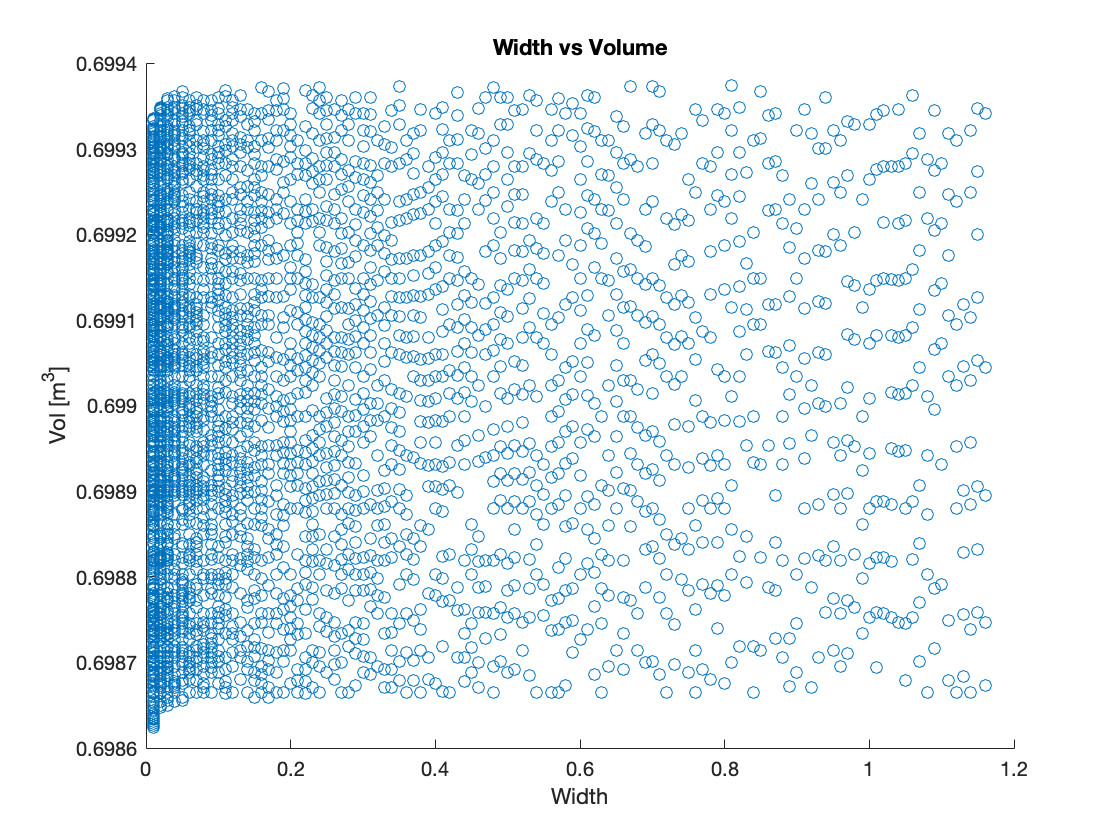

%%%%%%%%% WIDTH PLOTS %%%%%%%%%
clf
scatter(Width, Vol)
title("Width vs Volume")
ylabel("Vol [m^3]")
xlabel('Width')

The Width vs Volume plot reveals that the volume remains very constant for all geometry variations. The constant volume of the HX must be corrolated with only one volume working with the fixed parameters S_fins and S_plates. Volume plots are not being displayed for the other varying parameters becasue of thsi constant trend. 

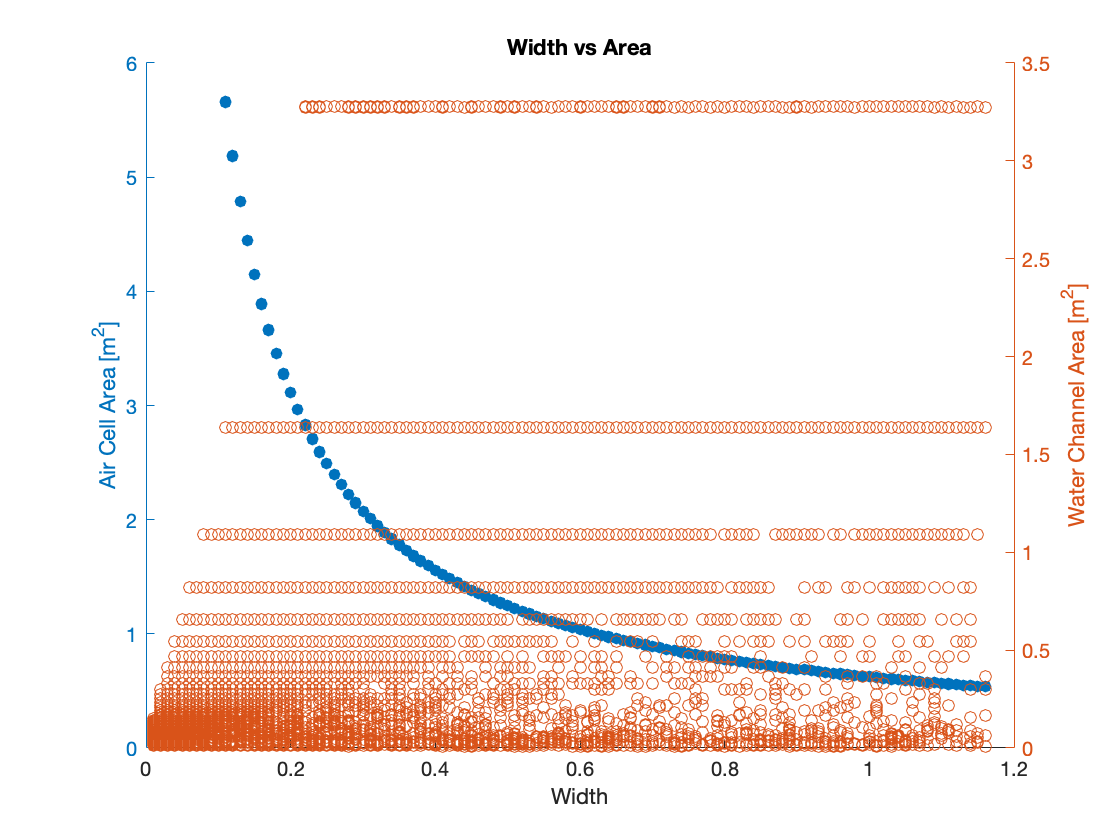


clf
hold on
xlabel('Width')

yyaxis left
title("Width vs Area")
ylabel("Air Cell Area [m^2]")
scatter(Width(2500:end), Area_Cold(2500:end), 'filled')
%hold on
yyaxis right
ylabel("Water Channel Area [m^2]")
scatter( Width, Area_Hot)

hold off

This plot shows that the water channnel area remains constant with width at different intervals. However, the air cell area expoentially decays as width becomes larger. A larger width corrolates to a larger pressure drop, which means that there must be less air cells to satisfy the pressure drop requirement.

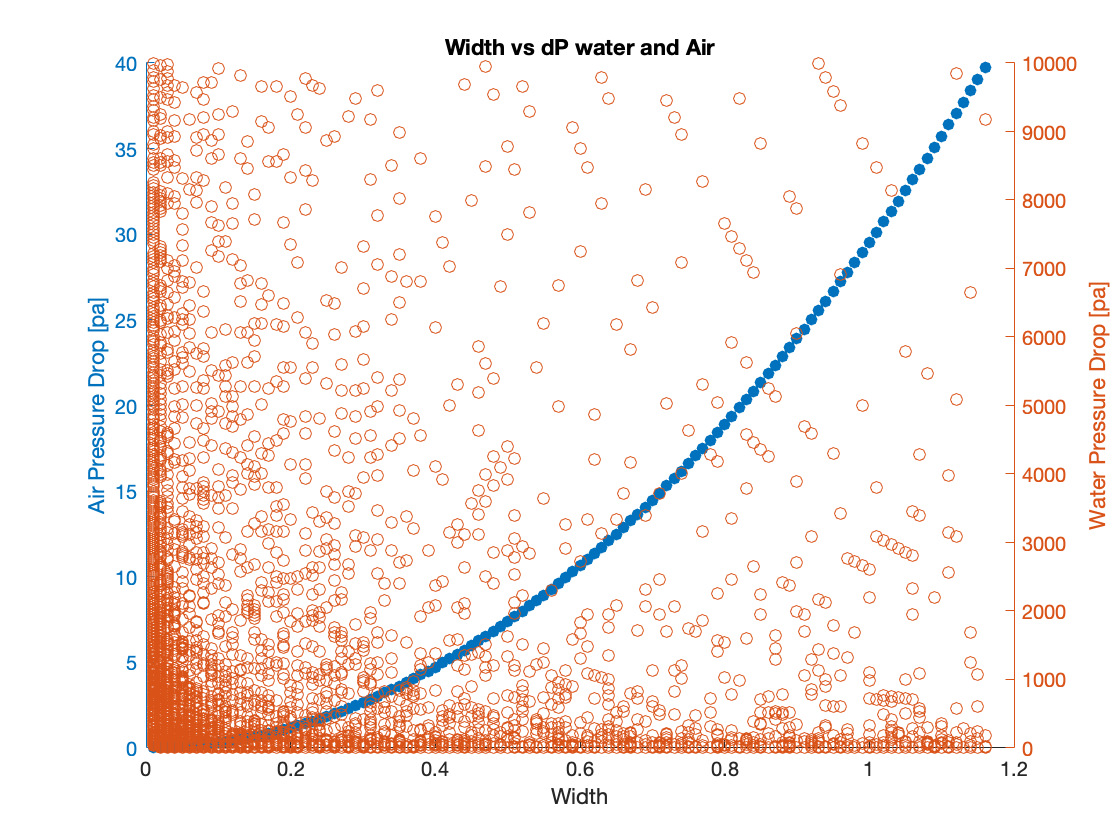

clf
hold on
title("Width vs dP water and Air")
xlabel('Width')

yyaxis left
ylabel("Air Pressure Drop [pa]")
scatter(Width,Pressure_air, 'filled')

yyaxis right
ylabel("Water Pressure Drop [pa]")
scatter( Width, Pressure_w)
hold off

There is no particular trend with the pressure drop in water because the air pressure drop is the limiting factor. The pressure drop is direcly porportional to Width and quickly reaches it's maximum.

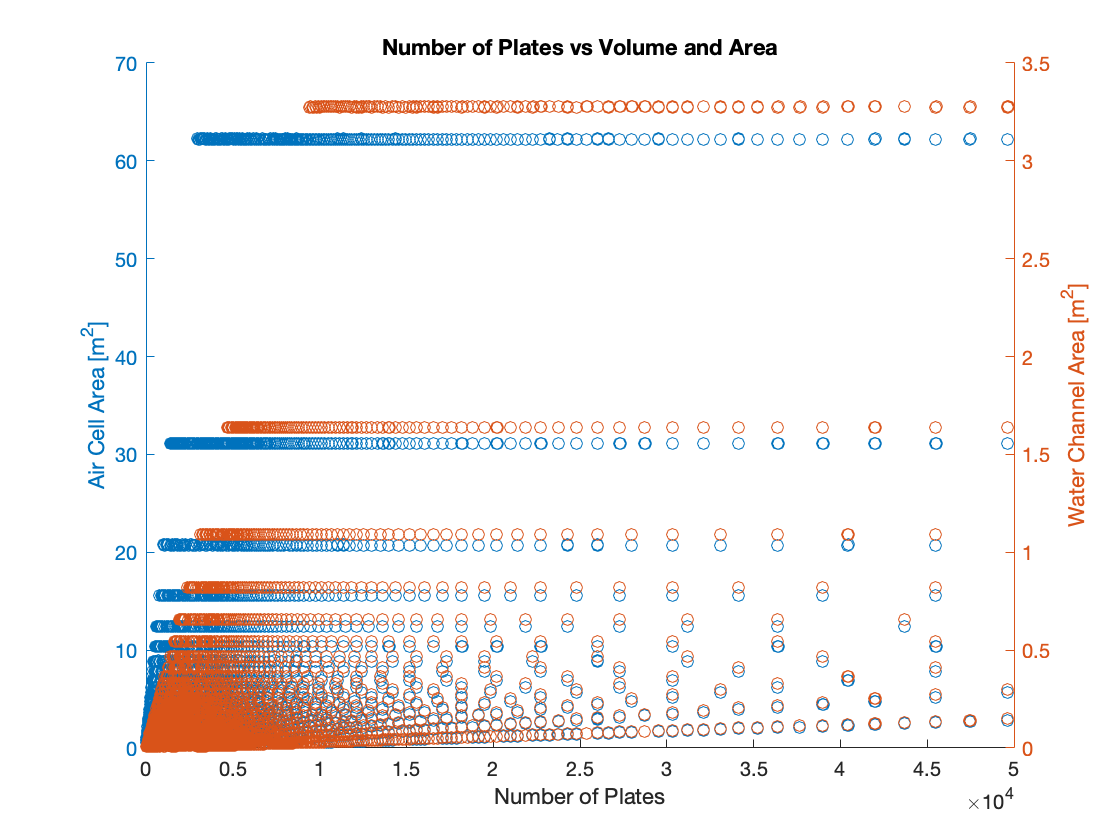


%%%%%%%%% N_Plates PLOTS %%%%%%%%%
clf
hold on
title("Number of Plates vs Volume and Area")
xlabel('Number of Plates')

yyaxis left
ylabel("Air Cell Area [m^2]")
%scatter(Number_plates,Vol)
scatter(Number_plates,Area_Cold)

yyaxis right
ylabel("Water Channel Area [m^2]")
scatter( Number_plates, Area_Hot)
hold off

Air cell and water channel area remains constant with the number of plates at different intervals, but begins to have less working geometries at higher numbers of plates. The constant air and water areas must mean that there are only a certain amount of areas that satisfy the requirements. 

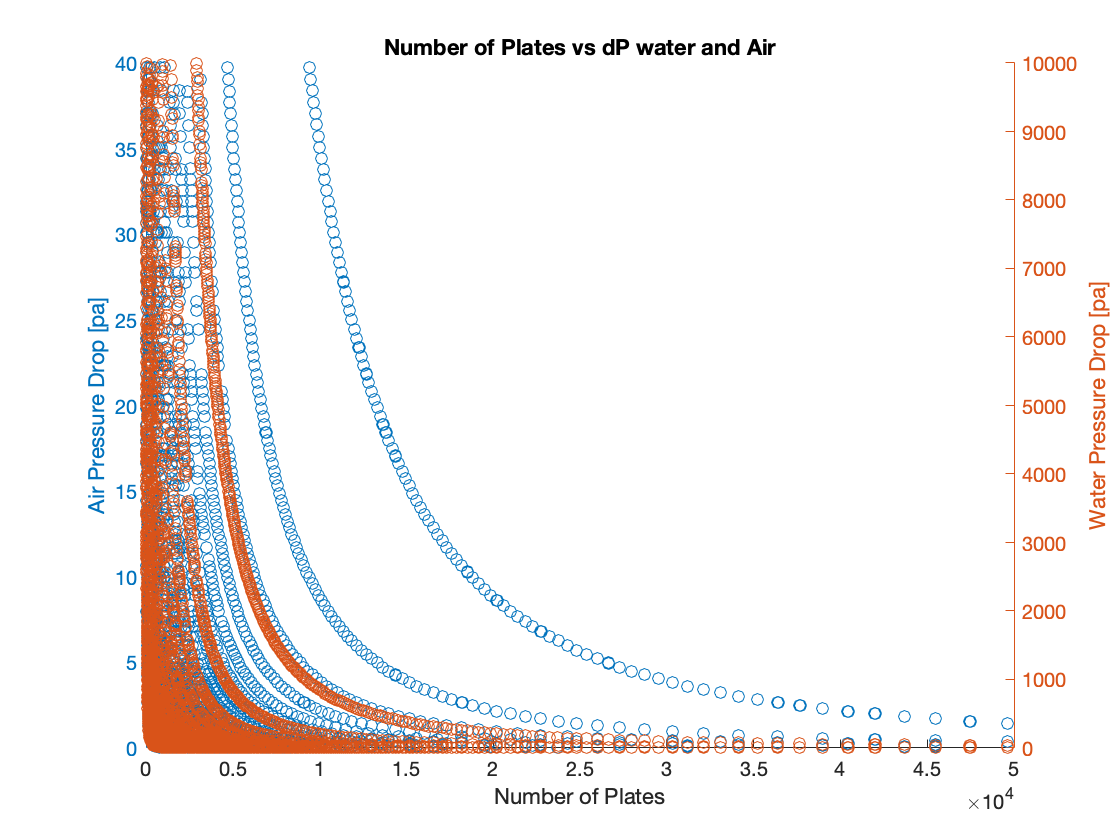


clf
hold on
title("Number of Plates vs dP water and Air")
xlabel('Number of Plates')

yyaxis left
ylabel("Air Pressure Drop [pa]")
scatter(Number_plates,Pressure_air)

yyaxis right
ylabel("Water Pressure Drop [pa]")
scatter( Number_plates, Pressure_w)
hold off

Both water and air pressure expoentially decrease as the number of plates increases. This is because a large number of water channels are related to a very short travel disatnce for both air and water. Thus, the incredibly short travel distance relates to a minor pressure drop. 

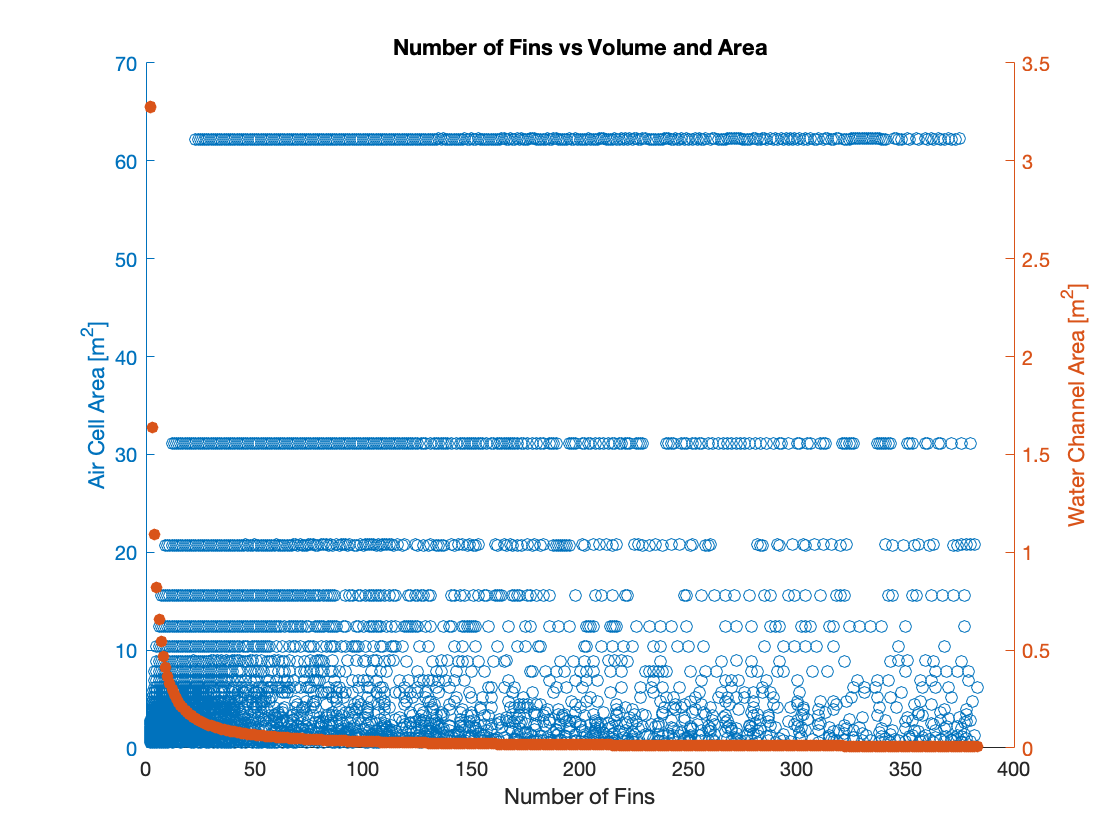

%%%%%%%%% N_fins PLOTS %%%%%%%%%
clf
hold on
title("Number of Fins vs Volume and Area")
xlabel('Number of Fins')

yyaxis left
ylabel("Air Cell Area [m^2]")
%scatter(Number_fins,Vol)
scatter(Number_fins,Area_Cold)

yyaxis right
ylabel("Water Channel Area [m^2]")
scatter( Number_fins, Area_Hot, 'filled')
hold off

Air cell area exponentially decays as width varies. However, the water channel area expoentially decays as the number of fins increases. The air cell area remeains constant at different intervals for the varying number of fins. This trend can be explained becasue the water channnels pressure drop is reliant on length and a larger number of fins means a longer HX. The longer the HX, the larger pressure drop per channel area, and thus there is less water channel area. 

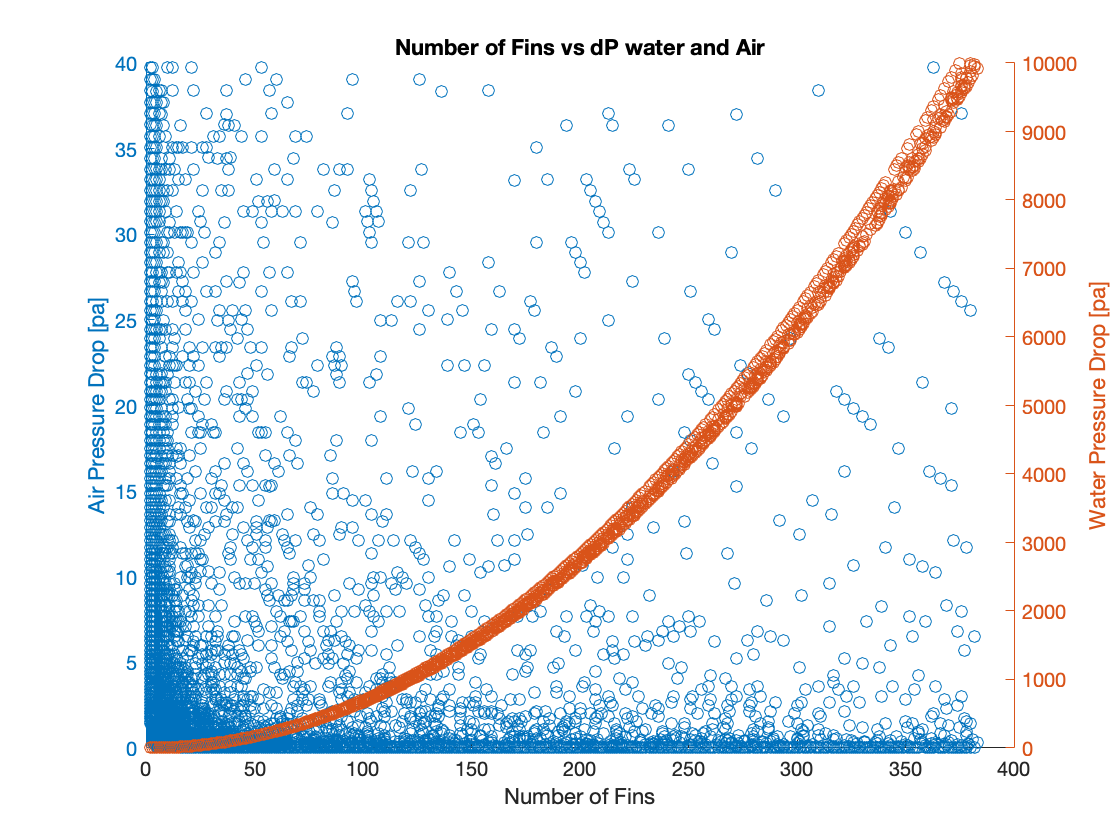

clf
hold on
title("Number of Fins vs dP water and Air")
xlabel('Number of Fins')

yyaxis left
ylabel("Air Pressure Drop [pa]")
scatter(Number_fins,Pressure_air)

yyaxis right
ylabel("Water Pressure Drop [pa]")
scatter( Number_fins, Pressure_w)
hold off

The number of fins ploted against pressure variation looks very similar to the varying width plotted against pressure varations. They differ because in the varying number of fins case, the water pressure drop is the limiting factor. Water pressure drop is a function of HX length while the air pressure drop is a funciton of width. 

%%%%%%%%% Table with Possible Geometries %%%%%%%%%
Geometery1=[1:(Geometery-1)];
ValidGeometeries = table(Geometery1',Width',Number_plates',Number_fins',Area_Hot',Area_Cold', Vol', 'VariableNames',{'Geometry','Width','Number of Plates','Number of Fins','Water Area', 'Air Area', 'Volume' })

ValidGeometeries = 5705×7 table
    Geometry    Width    Number of Plates    Number of Fins    Water Area    Air Area    Volume 
    ________    _____    ________________    ______________    __________    ________    _______

        1       0.01          49620                23           0.14886       62.203     0.69866
        2       0.01          49625                23           0.14888       62.209     0.69873
        3       0.01          49630                23           0.14889       62.215      0.6988
        4       0.01          49635                23           0.14891       62.222     0.69887
        5       0.01          49640                23           0.14892       62.228     0.69895
        6       0.01          49645               

summary(ValidGeometeries)

Variables:

    Geometry: 5705×1 double

        Values:

            Min            1  
            Median      2853  
            Max         5705  

    Width: 5705×1 double

        Values:

            Min         0.01  
            Median      0.15  
            Max         1.16  

    Number of Plates: 5705×1 double

        Values:

            Min           25  
            Median      4045  
            Max        49670  

    Number of Fins: 5705×1 double

        Values:

            Min           2   
            Median       34   
            Max         383   

    Water Area: 5705×1 double

        Values:

            Min       0.00837 
            Median    0.09927 
            Max        3.2782 

    Air Area: 5705×1 double

        Values:

            Min       0.53624 
            Median     4.1502 
            Max        62.263 

    Volume: 5705



%%%%%%%%% Minimum Volume and Coresponding Values %%%%%%%%%
[Min_Vol, i] = min(Vol);
Min_Vol

Min_Vol = 0.6986

Min_W = Width(i)

Min_W = 0.0100

Min_N_fins = Number_fins(i)

Min_N_fins = 101

Min_N_plates = Number_plates(i)

Min_N_plates = 10915

Min_Height = S_plate*Min_N_plates

Min_Height = 87.3200

Min_L = S_fin*(Min_N_fins)

Min_L = 0.8080